# Matlab Graph Scatter Plot Examples

**back to** [**Fan**](https://fanwangecon.github.io)**'s** [**Reusable Matlab**](https://fanwangecon.github.io/M4Econ/)** Repository or** [**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repository**

## Scatter Plot Example

The plot below as square scatter points, each one with think border. Can set transparency of border/edge and inside separately.

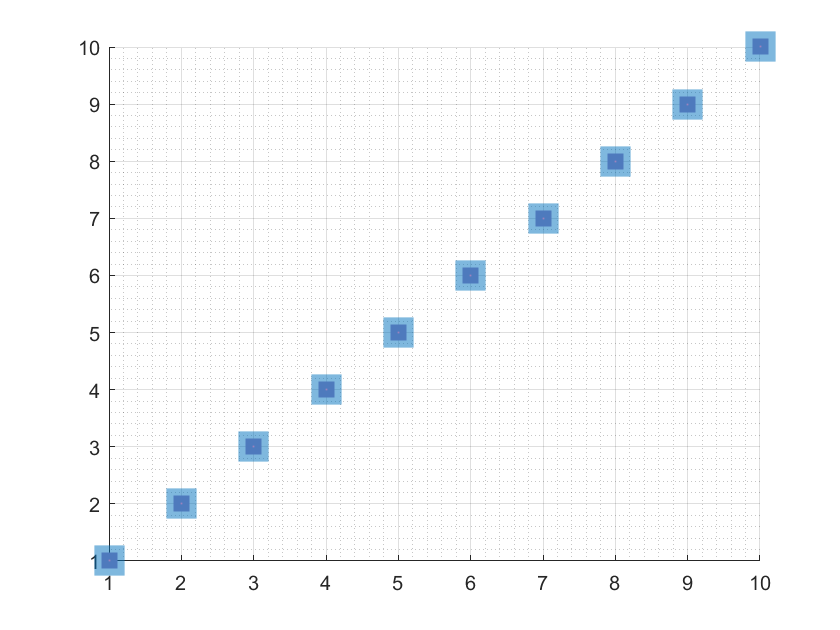

close all;
figure();
size = 100;
s = scatter(1:10,1:10,size);

s.Marker = 's';
% color picked by using: uisetcolor
s.MarkerEdgeColor = [0    0.4471    0.7412];
s.MarkerEdgeAlpha = 0.5;
s.MarkerFaceColor = [.61 .51 .74];
s.MarkerFaceAlpha = 1.0;
s.LineWidth = 10;
grid on;
grid minor;

% 'o'	Circle
% '+'	Plus sign
% '*'	Asterisk
% '.'	Point
% 'x'	Cross
% 'square' or 's'	Square
% 'diamond' or 'd'	Diamond
% '^'	Upward-pointing triangle
% 'v'	Downward-pointing triangle
% '>'	Right-pointing triangle
% '<'	Left-pointing triangle
% 'pentagram' or 'p'	Five-pointed star (pentagram)
% 'hexagram' or 'h'	Six-pointed star (hexagram)
% 'none'	No markers

## Scatter with Edge and Face Color and Transparency

Here is another way to Set Scatter Edge and Fac Colors and Transparencies.

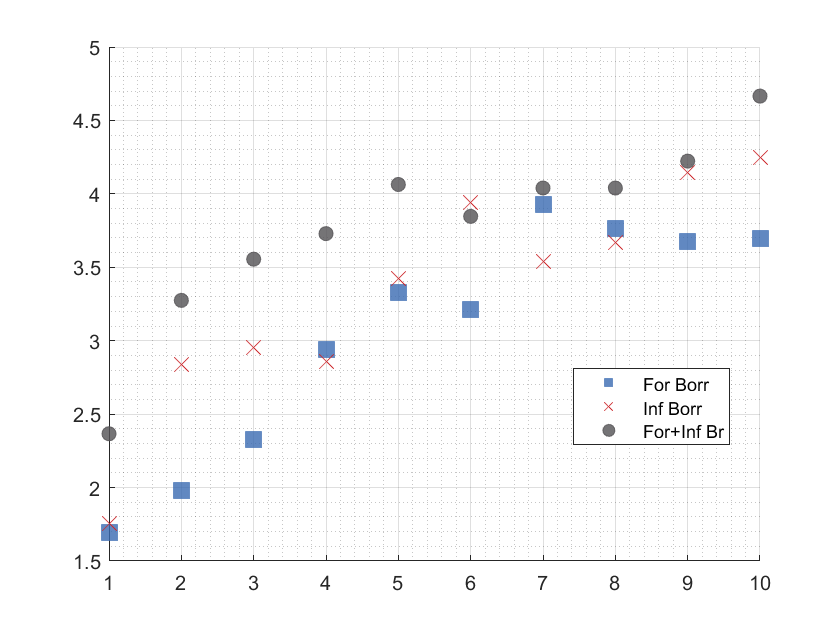

% Generate Data
rng(123);
it_x_n = 10;
it_x_groups_n = 3;
mat_y = rand([it_x_n, it_x_groups_n]);
mat_y = mat_y + sqrt(1:it_x_groups_n);
mat_y = mat_y + log(1:it_x_n)';
ar_x = 1:1:it_x_n;

% Colors
blue = [57 106 177]./255;
red = [204 37 41]./255;
black = [83 81 84]./255;
green = [62 150 81]./255;
brown = [146 36 40]./255;
purple = [107 76 154]./255;
cl_colors = {blue, red, black, ...
             green, brown, purple};

% Scatter Shapes
cl_scatter_shapes = {'s','x','o','d','p','*'};
% Scatter Sizes
cl_scatter_sizes = {100,100,50,50,50,50};
% Legend Keys
cl_legend = {'For Borr', 'Inf Borr', 'For+Inf Br'};

% Plot
figure();
hold on;
for it_m = 1:it_x_groups_n
    scatter(ar_x, mat_y(:,it_m), cl_scatter_sizes{it_m}, ...
        'Marker', cl_scatter_shapes{it_m}, ...
        'MarkerEdgeColor', cl_colors{it_m}, 'MarkerFaceAlpha', 0.8, ...
        'MarkerFaceColor', cl_colors{it_m}, 'MarkerEdgeAlpha', 0.8);
    cl_legend{it_m} = cl_legend{it_m};
end
legend(cl_legend, 'Location', 'best');
grid on; 
grid minor;